# lindex

複数の条件を組み合わせた実験や解析での線形インデックスを管理するクラス

## メンバ関数

### 作成

### 条件リスト登録

### 読み出し

## 使い方

x，y軸に沿って3点ずつ，各点について2種の周波数のでの測定を行う場合を考える．まず条件のリストとそれぞれの変数のラベルを作成する．

var_label = ["x", "y", "frequency"];
condition_list = [...
    0.0 0.0 4e6;...
    0.0 0.0 6e6;...
    0.0 1.0 4e6;...
    0.0 1.0 6e6;...
    0.0 2.0 4e6;...
    0.0 2.0 6e6;...
    0.0 0.0 4e6;...
    0.0 0.0 6e6;...
    1.0 0.0 4e6;...
    1.0 0.0 6e6;...
    2.0 0.0 4e6;...
    2.0 0.0 6e6;...
    ];

この条件リストに基づいてlindexを作成する．条件が重複している場合，"count"の列が自動的に追加され，連番が付される．

li = common.lindex(var_label, condition_list )

li =           x    y    frequency    [count]
          _    _    _________    _______

    1     0    0      4e+06         1   
    2     0    0      6e+06         1   
    3     0    1      4e+06         1   
    4     0    1      6e+06         1   
    5     0    2      4e+06         1   
    6     0    2      6e+06         1   
    7     0    0      4e+06         2   
    8     0    0      6e+06         2   
    9     1    0      4e+06         1   
    10    1    0      6e+06         1   
    11    2    0      4e+06         1   
    12    2    0      6e+06         1   


条件の指定は軸名=値を用いることができる．

li(frequency=4e6)

ans =      1
     3
     5
     7
     9
    11


複数の値を指定する場合は，値にリストを指定する

li(y=[1 2])

ans =      3
     4
     5
     6


範囲を指定する場合は，上限と下限の値をセルで渡す．例えばxの範囲が0.5~2.5の間にあるインデックスは，

li(x={0.5,2.5})

ans =      9
    10
    11
    12


で得られる．また，ある軸の値をすべて欲しいときは，ドットを用いて指定する

li.y

ans =      0
     0
     1
     1
     2
     2
     0
     0
     0
     0


上記のインデックスの指定と組み合わせると，指定の条件を満たした行の変数の値も手に入る．

idx = li(frequency=4e6);
li.y(idx)

ans =      0
     1
     2
     0
     0
     0


さて，作成したlindexの条件に従って実験を行う場合を考える．波形の記録用の配列としてwaveformsを用意しておく．また，実験を模すために，ダミーデータ作成用の関数を用いる．実際にはもちろんオシロスコープなどの入力がこれに代わることになる．

timevec = (0:0.01:10)*1e-6;
waveforms = zeros(numel(li), numel(timevec));
dummy_measure = @(tvec, x, y, freq) (y+1)*exp(-(tvec-1e-6*(x+3)).^2/1e-12).*cos(2*pi*freq*tvec);

実験条件を変えながら測定する実験プログラムは下記のようになる．配列waveformsには実験ごとの全ての波形が記録される．

for i=1:numel(li)
    meas_x = li.x(i);
    meas_y = li.y(i);
    meas_freq = li.frequency(i);
    waveforms(i,:) = dummy_measure(timevec, meas_x, meas_y, meas_freq);
end

さて，実験後の解析プログラムで，周波数6MHzで，地点x＝1,y＝0で測定したデータを取り出し，可視化することを考える．

idx = li(x = 1, y = 0, frequency = 6e6)

idx = 10

plot(timevec, waveforms(idx,:));
title("x=1, y=0, frequency = 6MHz");

y=0に沿って，4MHzのデータを可視化する．count = 1を指定することで，1回目に測定したデータのみを見ることができる．

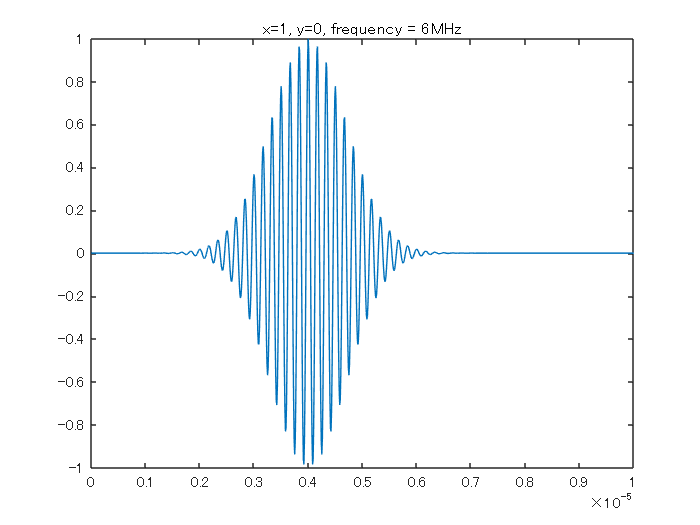

indices = li(y=0, frequency = 4e6, count = 1);
tiledlayout(numel(indices), 1);

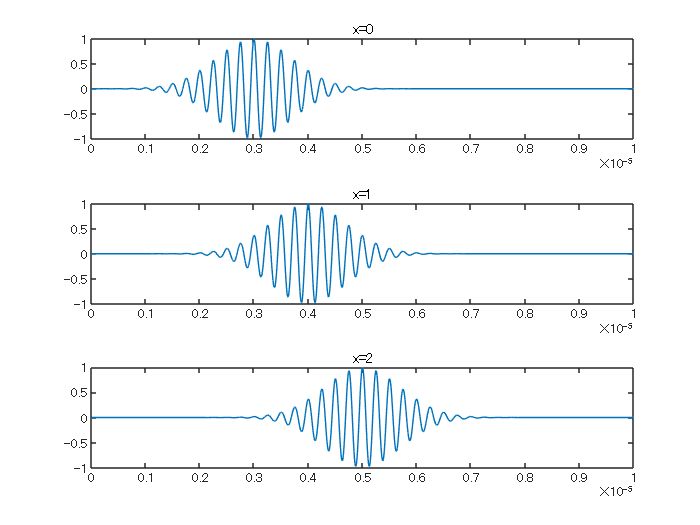

for i = 1:numel(indices)
    idx = indices(i);
    nexttile
    this_x = li.x(idx);
    plot(timevec, waveforms(idx,:));
    title("x=" + this_x);
end

全ての波形に処理を行ったあとに，処理後のデータをfreqdomainに格納する．x軸の値によって，窓の位置を変えてフーリエ変換を行う．また送信周波数によって，フーリエ変換後のピークを取る周波数の範囲を変える．

freqdomain = zeros(numel(li),numel(timevec));
peakComponent = zeros(numel(li),1);
for idx = 1:numel(li)
    this_x = li.x(idx);
    this_f = li.frequency(idx);
    [freqdomain(idx,:), freqvec] = common.wfft(waveforms(idx, :), timevec, (this_x+2)*1e-6, (this_x+4)*1e-6);
    peakComponent(idx) = common.gatedMax(abs(freqdomain), freqvec, this_f-1e6, this_f+1e6);
end

yの位置を横軸にピークの値をプロットさせる

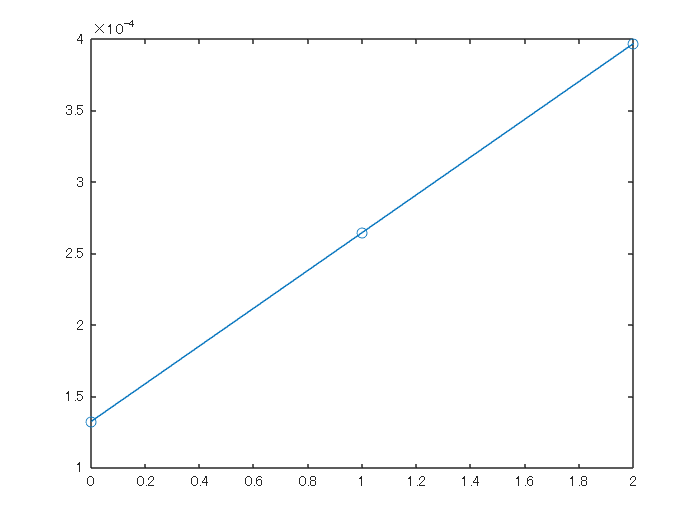

figure
indices = li(x=0, frequency = 6e6, count = 1);
y_list = li.y(indices);
plot(y_list, peakComponent(indices),"o-");

## 解説

実験条件の変数（条件変数）が多い場合，各条件ごとのデータの格納方法は，おおむね2通りである．

- 多次元インデックスを使う：多次元配列・セルを用いて，次元ごとに条件変数を割り当てる．

- 線形インデックスを使う：条件変数をまとめて条件変数を一つにした上で，データ次元＋1の次元の配列やセル配列にまとめた条件ごとのデータを格納する．

いずれの方法にも短所がある．1の方法の短所は下記の通り．

- 多次元配列の添字の順番の間違いに気づきにくい．

- 一度作成したプログラムに新たに軸を加えるときにはデータの作成側（測定プログラム）も，使用側（解析プログラム）も大きな変更が必要になりがち．そのためプログラムの使い回しが面倒．

- 全ての変数に対して網羅的に取らない場合にデータ容量の効率が落ちる．

- 同じ条件で複数回重複して測定した場合に，（上書きしてしまえば簡単だが）全部保存しようとすると，もう1軸増やさなければならず，管理が面倒．またプログラムも複雑化する．

- ある条件を変えると別の条件の刻みや測定回数を変えたい場合は，基本的に対応が難しい．

2の線形インデックスを使う方法の短所は下記の通り

- 線形インデックスから各変数を知るのは楽だが，ある変数の結果がどのインデックスにあるのかを知るのは，面倒なことが多く，間違えやすい．変数1を固定して変数2を振った結果を知りたくても，どのインデックスから始まるかは，計算が面倒だし，インデックスが連番になっているとも限らない．

`lindex`は2の線形インデックスを使う方法を支援するためのクラスである．2の短所である，変数⇒インデックスの「検索」を短く書けるため，解析の際のコードを減らすことができる．